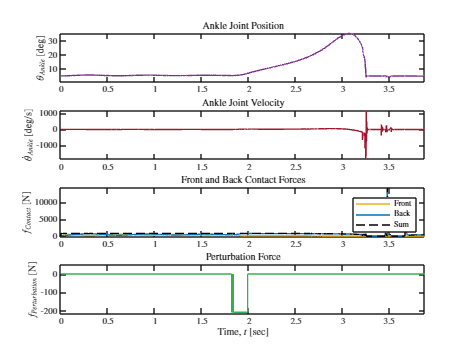

set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaulttextinterpreter','latex');

constraint_data = importdata("constraint_frc_data");
perturbation_data = importdata('perturbation_data');
joint_pos = importdata('joint_position_data');
joint_vel = importdata('joint_velocity_data');
contact_frc_data = importdata('contact_force_sensor');

% Sample data for plotting
x = constraint_data(:,1);
y1 = joint_pos(2:end,2);
y2 = joint_vel(:,2);
y3 = contact_frc_data(:,2);
y4= contact_frc_data(:,3);
sum=y3+y4;
% y3 = constraint_data(:,2);
% y4 = constraint_data(:,3);

% Create a new figure
figure;

% Draw vertical lines
lineX = [3, 6, 8]; % x-values where vertical lines should be drawn
lineY = [min(y4), max(y4)]; % y-limits for the vertical lines

% Subplot 1
subplot(4, 1, 1);
plot(x(2:end), y1, 'Color',[0.4940 0.1840 0.5560]);
title('Ankle Joint Position');
ylabel('$\theta_{Ankle}$ [deg]');
% set(gca, 'xtick', []); % Turn off x-axis ticks
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], [min(y1), max(y1)], 'Color', 'b', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
axis([min(x), max(x), min(y1)-3, max(y1)]);

% Subplot 2
subplot(4, 1, 2);
plot(x, y2, 'Color', [0.6350 0.0780 0.1840]);
title('Ankle Joint Velocity');
ylabel('$\dot{\theta}_{Ankle}$ [deg/s]')
% set(gca, 'xtick', []); % Turn off x-axis ticks
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], [min(y2), max(y2)], 'Color', 'k', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
axis([min(x), max(x), min(y2)-2.5, max(y2)+2.5]);

% Subplot 3
subplot(4, 1, 3);
plot(x, y3, 'Color',[0.9290 0.6940 0.1250]);
hold on;
plot(x,y4, 'Color',[0 0.4470 0.7410]);
hold on;
plot(x,sum, 'k--');
hold on;
title('Front and Back Contact Forces');
ylabel('$\it{f_{Contact}}$ [N]');
% set(gca, 'title', []); % Turn off x-axis ticks
% set(gca, 'xtick', []); % Turn off x-axis ticks
% xlabel('Time, $\it{t}$ [sec]')
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], [min(y3), max(y3)], 'Color', 'k', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
legend('Front', 'Back', 'Sum','Location','southeast');
axis([min(x), max(x), min(sum)-10, max(sum)+50]);

% Subplot 4
subplot(4, 1, 4);
plot(x, perturbation_data(:,2), 'Color', [0.2 0.7 0.3]);
title('Perturbation Force');
ylabel('$\it{f_{Perturbation}}$ [N]')
xlabel('Time, $\it{t}$ [sec]'); % Label the x-axis for the bottom subplot
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], lineY, 'Color', 'k', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
axis([min(x), max(x), min(perturbation_data(:,2))-5, max(perturbation_data(:,2))+50]);

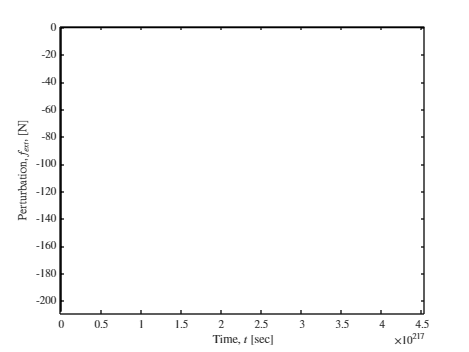


% % Adjusting subplot spacing
% spacing = 0.05;
% position = get(gca, 'Position');
% position(3) = position(3) + spacing*3;
% position(2) = position(2) + spacing;
% position(4) = position(4) - spacing * 2;
% set(gca, 'Position', position);

figure;
title('Perturbation versus Time');
plot(perturbation_data(:,1), perturbation_data(:,2),'Color', 'k', 'LineStyle', '-');
hold on;
axis([min(perturbation_data(:,1)), max(perturbation_data(:,1)), min(perturbation_data(:,2))-1, max(perturbation_data(:,2))+1]);
ylabel('Perturbation, $\it{f_{ext}}$, [N]');
xlabel('Time, $\it{t}$ [sec]');